
clear;
% Load Accel / Gyro Training data
AccelGyroCalib = load("calib2_straight.mat");

% Load Magnetometer data
MagCalib = load("calib1_rotate.mat");


% Extract accelerometer and gyro data
accel = squeeze(permute(AccelGyroCalib.out.Sensor_ACCEL.signals.values, [3, 2, 1]));
gyro  = squeeze(permute(AccelGyroCalib.out.Sensor_GYRO.signals.values, [3, 2, 1]));
t = AccelGyroCalib.out.Sensor_ACCEL.time;
rotQuat = AccelGyroCalib.out.GT_rotation.signals.values;
eulAngles = quat2eul(rotQuat);
yawGT = eulAngles(:,1) + pi;

% Calib1 (rotate) time
t_mag = MagCalib.out.Sensor_MAG.time;


% Extract second accelerometer data
accel2 = squeeze(permute(AccelGyroCalib.out.Sensor_LP_ACCEL.signals.values, [3, 2, 1]));

% Extract Magnetometer Data (rotation)
mag = squeeze(permute(MagCalib.out.Sensor_MAG.signals.values, [3, 2, 1]));


% Do same for still data
mag_still = squeeze(permute(AccelGyroCalib.out.Sensor_MAG.signals.values, [3, 2, 1]));



% Extract TOF data
tof_left = squeeze(AccelGyroCalib.out.Sensor_ToF1.signals.values(:,1,:));
tof_middle  = squeeze(AccelGyroCalib.out.Sensor_ToF2.signals.values(:,1,:));
tof_right = squeeze(AccelGyroCalib.out.Sensor_ToF3.signals.values(:,1,:));


% Define rotation matrices
Rotw_a = [0 1 0;
       0 0 1;
      -1 0 0]; % Accelerometer / Gyro

Rotw_a2 = [1 0 0;
        0 0 -1;
        0 1 0]; % Accelerometer 2

Rotw_mag = [0 1 0;
         0 0 1;
         1 0 0]; % Magnetometer

accel_corrected = (Rotw_a * accel')'; 
gyro_corrected = (Rotw_a * gyro')';

accel2_corrected = (Rotw_a2 * accel2')';

mag_corrected = (Rotw_mag * mag')';

mag_still_corrected = (Rotw_mag * mag_still')';


% Filter data where t < 60
idx = t < 60;  % Logical index where time is less than 60
t = t(idx);
accel_corrected = accel_corrected(idx, :);
gyro_corrected = gyro_corrected(idx,:);

% Extract TOF data and apply time filter
tof_left = tof_left(idx);
tof_middle = tof_middle(idx);
tof_right = tof_right(idx);

accel2_corrected = accel2_corrected(idx, :);

% Find Accelerometer and Gyro Bias and std
accel_bias = mean(accel_corrected);
gyro_bias = mean(gyro_corrected);

accel2_bias = mean(accel2_corrected);

R_accel = cov(accel_corrected);
R_gyro = cov(gyro_corrected);

R_accel2 = cov(accel2_corrected);

% Compute variances (1x1 covariance matrices)
R_tof_left = var(tof_left);
R_tof_middle = var(tof_middle);
R_tof_right = var(tof_right);


% Perform magnetometer calibration
[A_mag, b_mag, ~] = magcal(mag_corrected);

% A_mag: Transformation matrix
% b_mag: Bias vector

mag_corrected = (mag_corrected - b_mag) * A_mag;

mag_still_corrected = (mag_still_corrected - b_mag) * A_mag;


% Use Magnetometer from static data to find std / covariance
R_mag = cov(mag_still);

% Extract yaw angle from static magnetometer
psi_meas = atan2(mag_still_corrected(:,2), mag_still_corrected(:,1));  % atan2(Y, X)

% Wrap to [-pi, pi] to avoid jumps
psi_meas = wrapToPi(psi_meas);

% Estimate yaw variance 
R_psi = var(psi_meas);



% Plot results
% figure(1)
% plot(t, accel_corrected)
% title('Accelerometer Information')
% xlabel('Time (s)')
% ylabel('Acceleration (m/s^2)')
% legend('X', 'Y', 'Z')
% grid on
% 
% figure(2)
% plot(t, gyro_corrected);
% title('Gyroscope Data');
% xlabel('Time (s)');
% ylabel('Angular Velocity (rad/s)');
% legend('X (Roll)', 'Y (Pitch)', 'Z (Yaw)');
% 
% figure(3)
% plot(t, accel2_corrected)
% title('Accelerometer 2 Information')
% xlabel('Time (s)')
% ylabel('Acceleration (m/s^2)')
% legend('X', 'Y', 'Z')
% grid on
% 
% figure;
% plot(t_mag, mag_corrected);
% title('Calibrated Magnetometer Data');
% xlabel('Time (s)');
% ylabel('Magnetic Field (µT)');
% legend('X', 'Y', 'Z');

% Print Accelerometer Covariance Matrix
disp('Accelerometer Covariance Matrix (R_accel):');

Accelerometer Covariance Matrix (R_accel):


disp(R_accel);

   1.0e-03 *

    0.0456   -0.0134   -0.0132
   -0.0134    0.0697    0.0705
   -0.0132    0.0705    0.1909




% Print Gyroscope Covariance Matrix
disp('Gyroscope Covariance Matrix (R_gyro):');

Gyroscope Covariance Matrix (R_gyro):


disp(R_gyro);

   1.0e-05 *

    0.1949    0.0095    0.0017
    0.0095    0.1492    0.0040
    0.0017    0.0040    0.1158




% Print Second Accelerometer Covariance Matrix
disp('Second Accelerometer Covariance Matrix (R_accel2):');

Second Accelerometer Covariance Matrix (R_accel2):


disp(R_accel2);

   1.0e-03 *

    0.1048    0.0287   -0.0165
    0.0287    0.6711   -0.0866
   -0.0165   -0.0866    0.3443




% Print Magnetometer Covariance Matrix
disp('Magnetometer Covariance Matrix (R_mag):');

Magnetometer Covariance Matrix (R_mag):


disp(R_mag);

   1.0e-10 *

    0.0902    0.0374   -0.2280
    0.0374    0.0363   -0.1476
   -0.2280   -0.1476    0.9258




% Display Tof Covariances
disp('ToF Sensor Covariances:');

ToF Sensor Covariances:


disp(['Left ToF: ', num2str(R_tof_left)]);

Left ToF: 4.4603e-06


disp(['Middle ToF: ', num2str(R_tof_middle)]);

Middle ToF: 7.7185e-05


disp(['Right ToF: ', num2str(R_tof_right)]);

Right ToF: 1.6871e-05



% Print Accelerometer Bias
disp('Accelerometer Bias (accel_bias):');

Accelerometer Bias (accel_bias):


disp(accel_bias);

    0.0275   -0.3963  -10.0025




% Print Gyroscope Bias
disp('Gyroscope Bias (gyro_bias):');

Gyroscope Bias (gyro_bias):


disp(gyro_bias);

   -0.0112   -0.0013   -0.0019




% Print Second Accelerometer Bias
disp('Second Accelerometer Bias (accel2_bias):');

Second Accelerometer Bias (accel2_bias):


disp(accel2_bias);

    0.4372    0.3573  -10.2280




% Print Magnetometer Bias (from magcal)
disp('Magnetometer Bias (b_mag):');

Magnetometer Bias (b_mag):


disp(b_mag);

   1.0e-04 *

   -0.5304    0.6372   -0.1037




%% === Magnetometer Interference Correction with Filtering ===
%mean(wrapToPi(atan2(mag)))
% Parameters
fs = 104;         % Sampling frequency
fc = 0.00002;         % Cutoff frequency (Hz)
[b, a] = butter(2, fc / (fs / 2));  % 2nd order Butterworth

% Filter accelerometer (X, Y) and magnetometer (X, Y)
accel_filt_x = filtfilt(b, a, accel_corrected(:,1));
accel_filt_y = filtfilt(b, a, accel_corrected(:,2));
mag_filt_x   = filtfilt(b, a, mag_corrected(:,1));
mag_filt_y   = filtfilt(b, a, mag_corrected(:,2));

% --- Ensure same length for X and Y axes
len = min([length(accel_filt_x), length(accel_filt_y), length(mag_filt_x), length(mag_filt_y)]);
accel_filt_x = accel_filt_x(1:len);
accel_filt_y = accel_filt_y(1:len);
mag_filt_x   = mag_filt_x(1:len);
mag_filt_y   = mag_filt_y(1:len);

% --- Linear fit: mag = offset - alpha * accel (fit -accel vs. mag)
[coeffs_x, ~] = polyfit(-accel_filt_x, mag_filt_x, 1);
alpha_x = coeffs_x(1);
offset_x = coeffs_x(2);

[coeffs_y, ~] = polyfit(-accel_filt_y, mag_filt_y, 1);
alpha_y = coeffs_y(1);
offset_y = coeffs_y(2);

% --- Apply correction
mag_corr_x = mag_filt_x - offset_x + alpha_x * accel_filt_x;
mag_corr_y = mag_filt_y - offset_y + alpha_y * accel_filt_y;

avg_yaw_gt = mean(unwrap(yawGT(1:len)))

avg_yaw_gt = 1.5224

mag_yaw_raw = atan2(mag_corr_y, mag_corr_x);
yaw_offset = avg_yaw_gt - mean(mag_yaw_raw)

yaw_offset = 1.4564

mag_yaw = (mag_yaw_raw)+yaw_offset;

disp(rad2deg([avg_yaw_gt, mean(mag_yaw), yaw_offset]))

   87.2259   87.2259   83.4438



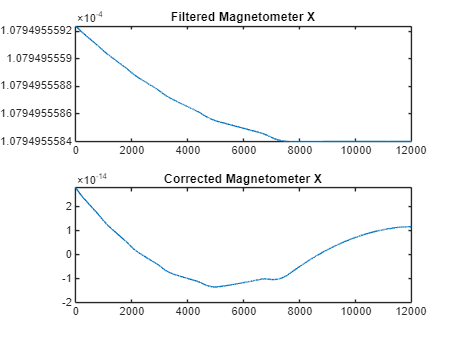



%% === Plots ===
figure;
subplot(2,1,1); plot(mag_filt_x); title('Filtered Magnetometer X');
subplot(2,1,2); plot(mag_corr_x); title('Corrected Magnetometer X');

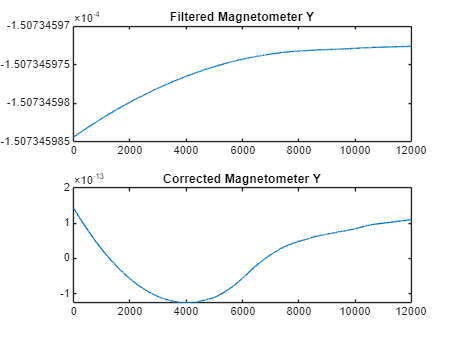


figure;
subplot(2,1,1); plot(mag_filt_y); title('Filtered Magnetometer Y');
subplot(2,1,2); plot(mag_corr_y); title('Corrected Magnetometer Y');

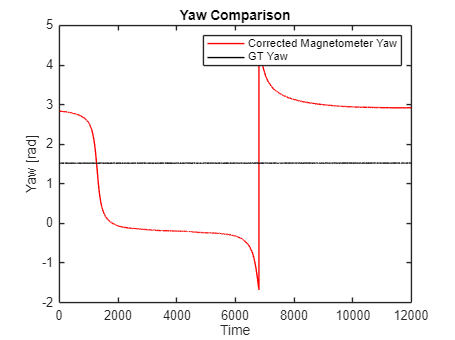


figure;
plot(mag_yaw, 'r'); hold on;
plot(wrapToPi(yawGT(1:len)), 'k');
legend('Corrected Magnetometer Yaw', 'GT Yaw');
title('Yaw Comparison');
xlabel('Time'); ylabel('Yaw [rad]');


%% === Output Parameters ===
disp("alpha_x = " + alpha_x)

alpha_x = 0.00018056


disp("alpha_y = " + alpha_y)

alpha_y = 0.0011781


disp("yaw_offset = " + yaw_offset);

yaw_offset = 1.4564



% --- Save updated calibration to .mat file
save('sensor_calibration2.mat', 'R_accel', 'R_gyro', 'R_accel2', 'R_mag', ...
    'accel_bias', 'gyro_bias', 'accel2_bias', 'b_mag', ...
    'R_tof_left', 'R_tof_middle', 'R_tof_right','Rotw_mag','Rotw_a','Rotw_a2','A_mag','b_mag', 'R_psi');

% --- Save new correction coefficients for use in EKF
save('sensor_calibration2.mat', '-append', 'alpha_x', 'alpha_y', 'yaw_offset');
